# 4 Sabendo que um processo de fabrico produz 30% de pecas defeituosas e considerando a variavel aleatoria X, representativa do numero de pecas defeituosas numa amostra de 5 pecas tomadas aleatoriamente, obtenha

## i) estimativa para a funcao massa de probabilidade de X;

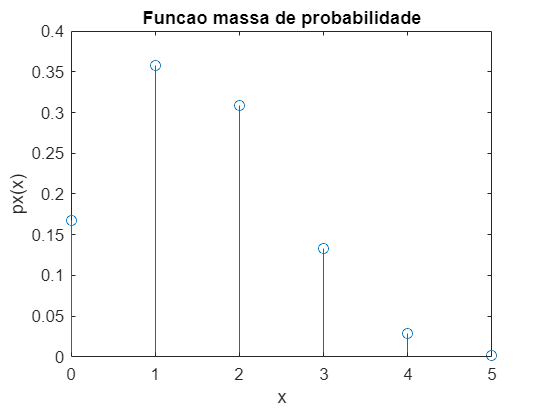

p = 0.3; % 30% prob
N = 1e5; % num exp
s = 0:5; % amostras vao de 0 a 5

for i=1 : 6
  k = i-1;
  pX(i) = fMassaProb(N,p,k,n);
end
stem(s,pX), xlabel('x'), ylabel('px(x)'), title('Funcao massa de probabilidade');

## i) ii. o grafico representativo da funcao distribuicao acumulada de probabilidades de X;

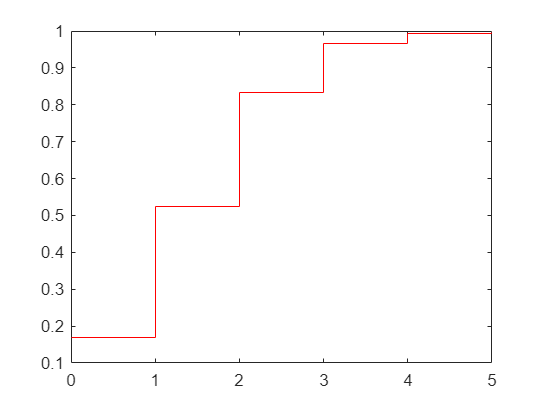

x = [0 1 2 3 4 5]; % amostras
fd = cumsum(pX);
stairs([0 1 2 3 4 5],fd,'r');

## iii. estimativa para probabilidade de, no maximo, 2 das pecas de uma amostra serem defeituosas.

fprintf("%f", pX(1) + pX(2) + pX(3))

0.833250

## b

%Analiticamente:

%Como X e uma variavel Binomial: %pX(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)
% i)
pXTeorica = zeros(1,6);
n = 5;   %Numero de pecas escolhidas
p = 3/10; %Probabilidade da peca ser defeituosa (=30/100 = 30%)

for k=0 : 5
  i = k+1;
  nCk = factorial(n)/(factorial(k) * factorial(n-k));
  pXTeorica(i) = nCk * p^k * (1-p)^(n-k);
end

pXTeorica;

figure(1);
hold on;

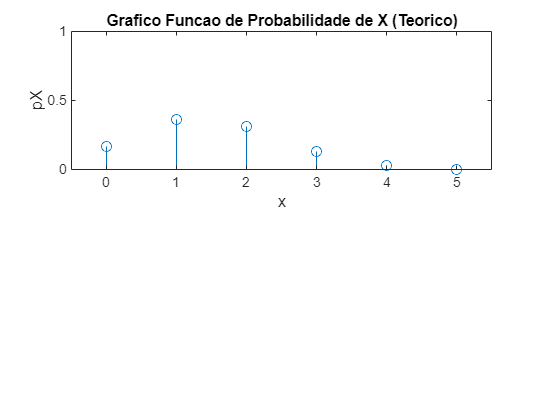


x = 0:5;

subplot(2,2,[1,2]);

stem(x,pXTeorica);

axis([-0.5 5.5 0 1]);
xlabel('x');
ylabel('pX');
title("Grafico Funcao de Probabilidade de X (Teorico)");


% ii)

%Analiticamente:
disp("Analiticamente:");

Analiticamente:



p = pXTeorica(1) + pXTeorica(2) + pXTeorica(3);
fprintf("P(Termos no maximo 2 pecas defeituosas) = %f\n",p);

P(Termos no maximo 2 pecas defeituosas) = 0.836920
